X1 = randn(50,2) + 1;
X2 = randn(51,2) - 1;

mean_x1 = [1 1];
mean_x2 = [-1 -1];

Y1 = ones(50,1);
Y2 = -ones(51,1);

% Get the slope of line between the two means
inv_slope = (mean_x1(2) - mean_x2(2)) / (mean_x1(1) - mean_x2(1));

% For perpendicular line, slope = -1/slope
slope = -1/inv_slope;

% Get midpoint
midx = (mean_x2(1) + mean_x1(1))/2;
midy = (mean_x2(2) + mean_x1(2))/2;

% Set x values for line plot
x = -3:0.25:3;

% calculate corresponding y-values
y = slope*(x - midx) + midy;



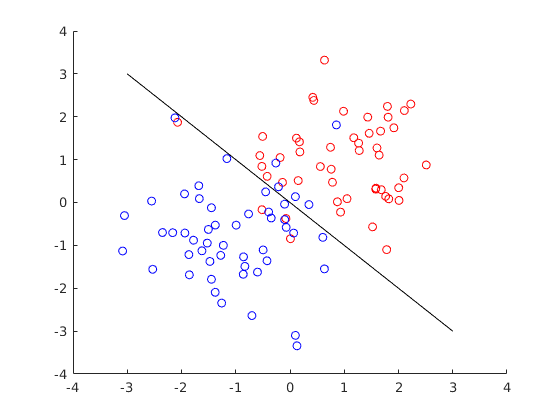

figure;
hold on;
plot(X1(:,1), X1(:,2), 'ro');
plot(X2(:,1), X2(:,2), 'bo');
plot(x, y, 'black');

%plot(mean_x1(1), mean_x1(2), 'go'); % center blue
%plot(mean_x2(1), mean_x2(2), 'go');
%plot([mean_x1(1) mean_x2(1)], [mean_x1(2) mean_x2(2)], 'g');
%plot(midx, midy, 'rx');
%line([x2,x], [sep2, sep1])
xlim([-4 4])
ylim([-4 4])
hold off;


saveas(figure,'myfigure.pdf')